# Nevronska mreža brez POS

## priprava podatkov


% Nalaganje podatkov
load('data.mat');

% razdelimo podatke na razrede in značilke
labels = data(:, 1);    % prvi stolpec so oznake razredov - labli
features = data(:, 2:end); % ostali stolpci so značilke

% Set the proportion of the data to be used for testing
testProportion = 0.3;
n = length(labels); % Total number of samples

% Generate a random permutation of the indices
perm = randperm(n);

% Determine the split index
splitIndex = round((1 - testProportion) * n);

% Split the data into training and testing sets
trainIndices = perm(1:splitIndex);
testIndices = perm(splitIndex+1:end);

trainData = data(trainIndices, :);
testData = data(testIndices, :);

% razdelimo podatke v testni in trening množici
trainFeatures = trainData(:, 2:end)';
trainLabels = trainData(:, 1)'; % Pravilno nastavi stolpce za oznake
testFeatures = testData(:, 2:end)';
testLabels = testData(:, 1)'; % Pravilno nastavi stolpce za oznake

% Normalizacija podatkov
[trainFeatures, mu, sigma] = zscore(trainFeatures'); % normaliziramo podatke na povprečje 0, standardni odklon 1
% mu in sigma sta povprečje in standardni odklon značilk
trainFeatures = trainFeatures';
testFeatures = (testFeatures' - mu) ./ sigma; % normiranje
testFeatures = testFeatures';

% Pretvorba oznak v binarno obliko (v binarne vektorje)
trainLabelsVec = ind2vec(trainLabels);
testLabelsVec = ind2vec(testLabels);


## Nevronska mreža

Konfiguracija 1:


Skriti sloji: [10 5 2]


Prenosna funkcija skritih slojev: purelin


Prenosna funkcija izhodnega sloja: purelin


Konfuzijska matrika (učni podatki):


     0     0     0
     3    14   140
     0     2   239



Konfuzijska matrika (testni podatki):


     4    51
     0   116



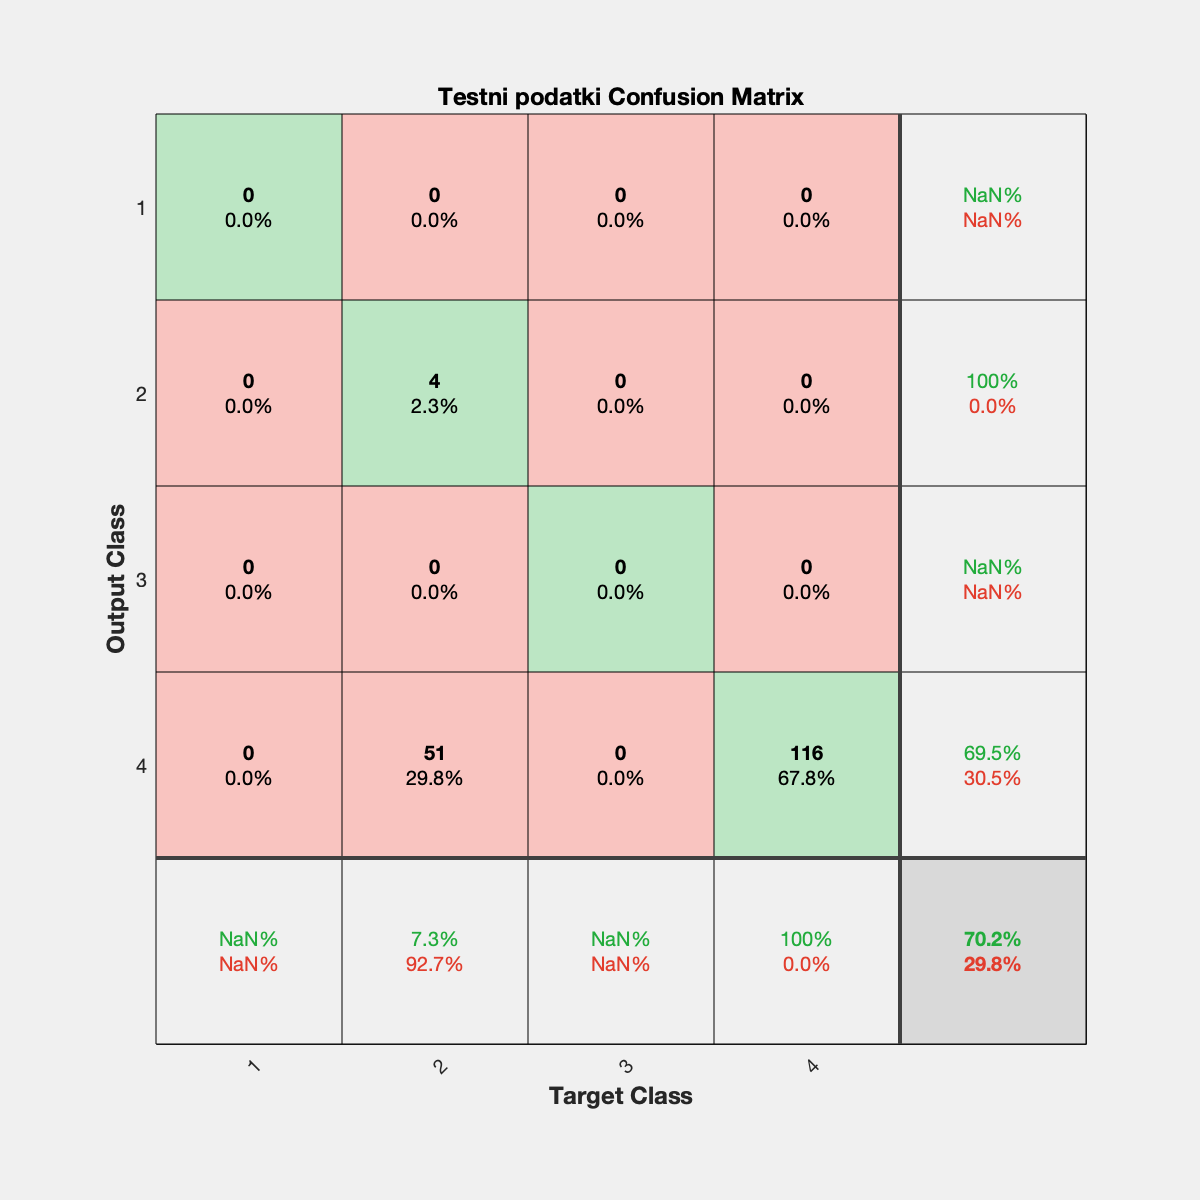

Natančnost (učni podatki): 63.57%


Natančnost (testni podatki): 70.18%


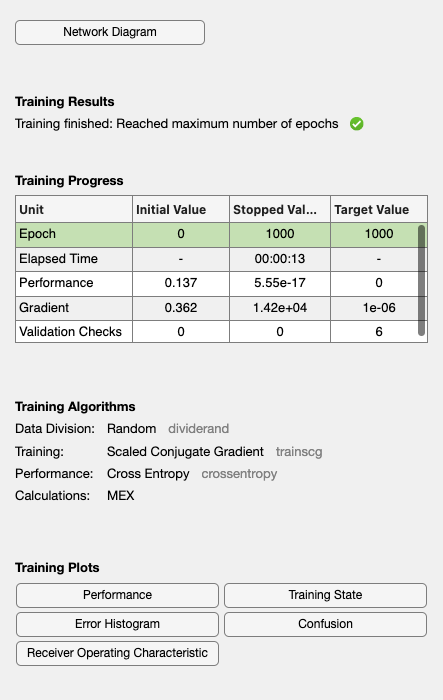

Konfiguracija 2:


Skriti sloji: [10 5 2]


Prenosna funkcija skritih slojev: poslin


Prenosna funkcija izhodnega sloja: purelin


Konfuzijska matrika (učni podatki):


     0   157
     0   241



Konfuzijska matrika (testni podatki):


     0    55
     0   116



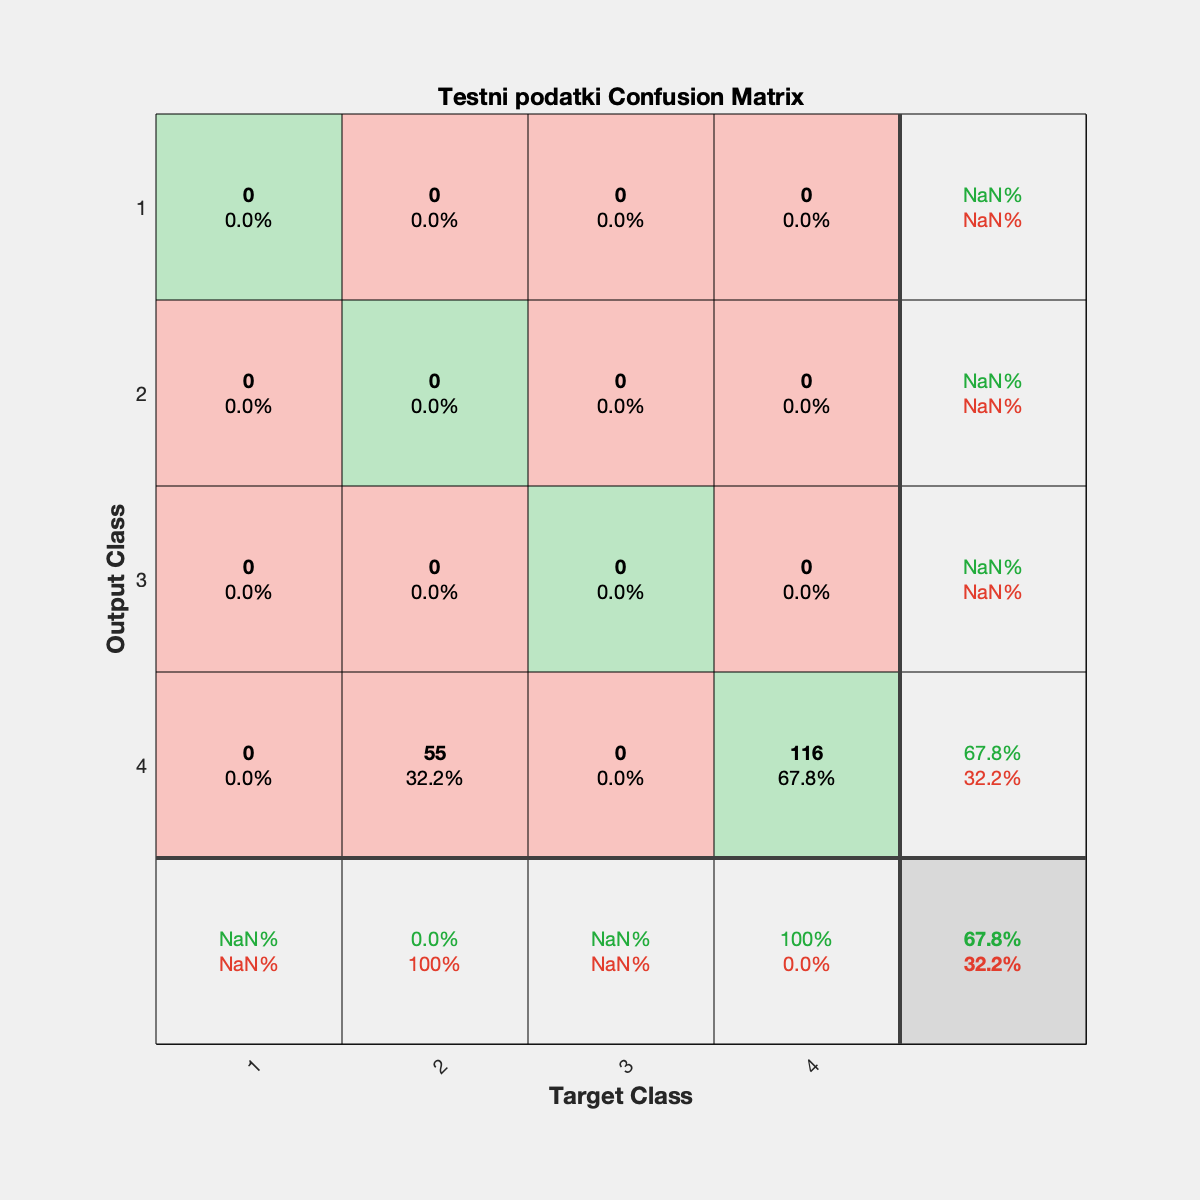

Natančnost (učni podatki): 60.55%


Natančnost (testni podatki): 67.84%



% Definicija mreže (več možnih konfiguracij)
configs = {
    
    {[10, 5, 2], 'purelin', 'purelin'}; % 3 skriti sloji (10, 5, 2 nevroni) z 'purelin'
    {[10, 5, 2], 'poslin', 'purelin'}; % 3 skriti sloji (10, 5, 2 nevroni) z 'poslin' in 'purelin'
};

for i = 1:length(configs)
    % konfiguracija posamezne nevronske mreže
    config = configs{i};
    hiddenLayerSizes = config{1}; % velikost skritih layerjev  
    hiddenTransferFcn = config{2}; % prenosna funkcija skritih layerjev
    outputTransferFcn = config{3}; % prenosna funkcija izhodnega layerja

    % Ustvarjanje mreže
    net = patternnet(hiddenLayerSizes);
    % Nastavi prenosne funkcije za vse skrite sloje
    for j = 1:length(hiddenLayerSizes)
        net.layers{j}.transferFcn = hiddenTransferFcn;
    end
    % Nastavi prenosno funkcijo za izhodni sloj
    net.layers{length(hiddenLayerSizes) + 1}.transferFcn = outputTransferFcn;

    % Delitev podatkov v MATLAB formatu
    net.divideFcn = 'dividerand';
    net.divideMode = 'sample';
    net.divideParam.trainRatio = 0.7;
    net.divideParam.valRatio = 0.15;
    net.divideParam.testRatio = 0.15;

    % Učenje mreže
    net = train(net, trainFeatures, trainLabelsVec);

    % Testiranje mreže
    predTrain = net(trainFeatures);
    predTest = net(testFeatures);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClass] = max(predTrain, [], 1);
    [~, predTestClass] = max(predTest, [], 1);

    % Analiza rezultatov
    trainConfMat = confusionmat(vec2ind(trainLabelsVec), predTrainClass);
    testConfMat = confusionmat(vec2ind(testLabelsVec), predTestClass);

    % Izpis rezultatov
    fprintf('Konfiguracija %d:\n', i);
    fprintf('Skriti sloji: %s\n', mat2str(hiddenLayerSizes));
    fprintf('Prenosna funkcija skritih slojev: %s\n', hiddenTransferFcn);
    fprintf('Prenosna funkcija izhodnega sloja: %s\n', outputTransferFcn);
    fprintf('Konfuzijska matrika (učni podatki):\n');
    disp(trainConfMat);
    fprintf('Konfuzijska matrika (testni podatki):\n');
    disp(testConfMat);

    % Risanje konfuzijske matrike
    figure;
    plotconfusion(trainLabelsVec, predTrain, 'Učni podatki');
    plotconfusion(testLabelsVec, predTest, 'Testni podatki');

    % Izračun natančnosti
    trainAccuracy = sum(diag(trainConfMat)) / sum(trainConfMat(:));
    testAccuracy = sum(diag(testConfMat)) / sum(testConfMat(:));
    
    % Prikaz natančnosti
    fprintf('Natančnost (učni podatki): %.2f%%\n', trainAccuracy * 100);
    fprintf('Natančnost (testni podatki): %.2f%%\n', testAccuracy * 100);

end

## POS optimizacija

clear all; close all; clc;
file = load('data.mat'); % Load the data
data_matrix = file.data; % Assuming 'data' is the variable name in the .mat file

% Separate data based on argument -- 357 benign, 212 malignant
malign_data = data_matrix(data_matrix(:,1)==2, :); % Data with argument 2
benign_data = data_matrix(data_matrix(:,1)==4, :); % Data with argument 4

% Set random seed for reproducibility
rng(1);

% Split data into train and test sets
train_ratio = 0.7; % Train ratio
malign_train_idx = randperm(size(malign_data, 1), round(train_ratio * size(malign_data, 1)));
benign_train_idx = randperm(size(benign_data, 1), round(train_ratio * size(benign_data, 1)));

malign_train_data = malign_data(malign_train_idx, :);
benign_train_data = benign_data(benign_train_idx, :);

train_data = [malign_train_data; benign_train_data];
test_data = setdiff(data_matrix, train_data, 'rows');

% Preparing inputs and targets
train_inputs = train_data(:, 2:end)';
train_targets = double(train_data(:, 1) > 2)';
test_inputs = test_data(:, 2:end)';
test_targets = double(test_data(:, 1) > 2)';

N_hidden = 5; % Number of hidden neurons
N_features = 31; % The first is diagnosis

configs = {
    {[10, 5, 2], 'purelin', 'purelin'}, % 3 hidden layers (10, 5, 2 neurons) with 'purelin'
    {[10, 5, 2], 'poslin', 'purelin'} % 3 hidden layers (10, 5, 2 neurons) with 'poslin' and 'purelin'
};

results = table('Size', [length(configs), 7], ...
    'VariableTypes', {'string', 'string', 'string', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Config', 'HiddenLayers', 'HiddenFcn', 'TrainAccuracy', 'TestAccuracy', 'TrainAccuracyPSO', 'TestAccuracyPSO'});

for i = 1:length(configs)
    % konfiguracija posamezne nevronske mreže
    config = configs{i};
    hiddenLayerSizes = config{1}; % velikost skritih slojev
    hiddenTransferFcn = config{2}; % prenosna funkcija skritih slojev
    outputTransferFcn = config{3}; % prenosna funkcija izhodnega sloja

    % Ustvarjanje mreže
    net = patternnet(hiddenLayerSizes);
    % Nastavi prenosne funkcije za vse skrite sloje
    for j = 1:length(hiddenLayerSizes)
        net.layers{j}.transferFcn = hiddenTransferFcn;
    end
    % Nastavi prenosno funkcijo za izhodni sloj
    net.layers{length(hiddenLayerSizes) + 1}.transferFcn = outputTransferFcn;

    % Delitev podatkov v MATLAB formatu
    net.divideFcn = 'dividerand';
    net.divideMode = 'sample';
    net.divideParam.trainRatio = 0.7;
    net.divideParam.valRatio = 0.15;
    net.divideParam.testRatio = 0.15;

    % Učenje mreže
    net = train(net, train_inputs, train_targets);

    % Testiranje mreže
    predTrain = net(train_inputs);
    predTest = net(test_inputs);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClass] = max(predTrain, [], 1);
    [~, predTestClass] = max(predTest, [], 1);

    % Analiza rezultatov
    trainConfMat = confusionmat(train_targets, predTrainClass - 1);
    testConfMat = confusionmat(test_targets, predTestClass - 1);

    % Izračun natančnosti
    trainAccuracy = sum(diag(trainConfMat)) / sum(trainConfMat(:));
    testAccuracy = sum(diag(testConfMat)) / sum(testConfMat(:));

    % PSO optimizacija
    [netPSO, global_best_fitness] = PSO_optimize(net, train_inputs, train_targets, 30, 50, 0.9, 0.4, 0.9, 2.1, 2.1, 0.2, 0.05, 0.1);

    % Testiranje PSO optimizirane mreže
    predTrainPSO = netPSO(train_inputs);
    predTestPSO = netPSO(test_inputs);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClassPSO] = max(predTrainPSO, [], 1);
    [~, predTestClassPSO] = max(predTestPSO, [], 1);

    % Analiza rezultatov PSO
    trainConfMatPSO = confusionmat(train_targets, predTrainClassPSO - 1);
    testConfMatPSO = confusionmat(test_targets, predTestClassPSO - 1);

    % Izračun natančnosti PSO
    trainAccuracyPSO = sum(diag(trainConfMatPSO)) / sum(trainConfMatPSO(:));
    testAccuracyPSO = sum(diag(testConfMatPSO)) / sum(testConfMatPSO(:));

    % Shranjevanje rezultatov v tabelo
    results.Config(i) = "Konfiguracija " + num2str(i);
    results.HiddenLayers(i) = mat2str(hiddenLayerSizes);
    results.HiddenFcn(i) = hiddenTransferFcn;
    results.TrainAccuracy(i) = trainAccuracy * 100;
    results.TestAccuracy(i) = testAccuracy * 100;
    results.TrainAccuracyPSO(i) = trainAccuracyPSO * 100;
    results.TestAccuracyPSO(i) = testAccuracyPSO * 100;
end

% Izpis vseh rezultatov na koncu
disp(results);

% Povprečna natančnost za linearne in nelinearne konfiguracije
linearConfigs = results(strcmp(results.HiddenFcn, 'purelin') | strcmp(results.HiddenFcn, 'poslin'), :);
nonlinearConfigs = results(~strcmp(results.HiddenFcn, 'purelin') & ~strcmp(results.HiddenFcn, 'poslin'), :);

avgTrainAccuracyLinear = mean(linearConfigs.TrainAccuracy);
avgTestAccuracyLinear = mean(linearConfigs.TestAccuracy);
avgTrainAccuracyLinearPSO = mean(linearConfigs.TrainAccuracyPSO);
avgTestAccuracyLinearPSO = mean(linearConfigs.TestAccuracyPSO);

avgTrainAccuracyNonlinear = mean(nonlinearConfigs.TrainAccuracy);
avgTestAccuracyNonlinear = mean(nonlinearConfigs.TestAccuracy);
avgTrainAccuracyNonlinearPSO = mean(nonlinearConfigs.TrainAccuracyPSO);
avgTestAccuracyNonlinearPSO = mean(nonlinearConfigs.TestAccuracyPSO);

fprintf('Povprečna natančnost (linearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyLinear);
fprintf('Povprečna natančnost (linearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyLinear);
fprintf('Povprečna natančnost PSO (linearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyLinearPSO);
fprintf('Povprečna natančnost PSO (linearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyLinearPSO);

fprintf('Povprečna natančnost (nelinearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyNonlinear);
fprintf('Povprečna natančnost (nelinearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyNonlinear);
fprintf('Povprečna natančnost PSO (nelinearne aktivacije, učni podatki): %.2f%%\n', avgTrainAccuracyNonlinearPSO);
fprintf('Povprečna natančnost PSO (nelinearne aktivacije, testni podatki): %.2f%%\n', avgTestAccuracyNonlinearPSO);

% PSO optimization function

function [net, global_best_fitness] = PSO_optimize(net, X_train, Y_train, N_particles, N_iterations, w, w_min, w_max, c1, c2, v_max, mutation_rate, mutation_scale)
    % Initialize particles
    net_params = length(getwb(net));
    particle_positions = repmat(getwb(net)', N_particles, 1);
    particle_velocities = zeros(N_particles, net_params);
    particle_personal_bests = particle_positions;
    particle_personal_best_fitnesses = inf(N_particles, 1);
    global_best = particle_positions(1,:);
    global_best_fitness = inf;
    
    % Optimization loop
    for i = 1:N_iterations
        r1 = rand(size(particle_positions)); 
        r2 = rand(size(particle_positions));
        particle_velocities = w*particle_velocities + c1*r1.*(particle_personal_bests - particle_positions) + c2*r2.*(repmat(global_best, N_particles, 1) - particle_positions);
        
        % Apply velocity limits
        particle_velocities(particle_velocities > v_max) = v_max; 
        particle_velocities(particle_velocities < -v_max) = -v_max;
        
        % Update positions
        particle_positions = particle_positions + particle_velocities;
        
        % Apply mutations
        for j = 1:N_particles
            if rand < mutation_rate
                r = randn(1, size(particle_positions, 2));
                particle_positions(j,:) = particle_positions(j,:) + mutation_scale*(r/max(r));
            end
        end
        
        % Apply position limits
        particle_positions(particle_positions > 1) = 1; 
        particle_positions(particle_positions < -1) = -1;
        
        % Evaluate fitness
        particle_fitnesses = zeros(N_particles, 1);
        for j = 1:N_particles
            net = setwb(net, particle_positions(j,:)');
            outputs = sim(net, X_train);
            errors = outputs - Y_train;
            particle_fitnesses(j) = sum(errors.^2) / length(Y_train);
            
            % Update personal best
            if particle_fitnesses(j) < particle_personal_best_fitnesses(j)
                particle_personal_bests(j,:) = particle_positions(j,:);
                particle_personal_best_fitnesses(j) = particle_fitnesses(j);
            end
            
            % Update global best
            if particle_fitnesses(j) < global_best_fitness
                global_best = particle_positions(j,:);
                global_best_fitness = particle_fitnesses(j);
            end
        end
        
        % Update inertia weight
        w = max(w - (w_max - w_min) / N_iterations, w_min);
        fprintf("Iteration %d - Global Best Fitness: %f\n", i, global_best_fitness);
    end
    
    % Set network to best found weights
    net = setwb(net, global_best');
end


